## Part 2 : Simulation

Based on the identified characterisitcs of the system, you are tasked to design a controller. You may design any other sub-systems such as planner, estimator, etc. However, they are not required. 

Write a thorough, yet concise report on methods of designing the controller.

### Author 

- Kantaka    Sirithanarattanakul    ID : 62340500002

- Keedita     Chaihetphon              ID : 62340500003

- Pakapak   Silpapinun                  ID : 62340500042

**Date **: 24 June 2021

## Description

To design the plant's controller, there are 3 main tasks to complate. First, creating the planner, we used the linear segment with parabolic blend as the trajectory equation. Second, we identify control-loop frequency and select the lowpass filter from system characteristics and requirements. Finally, we identified PID's constant as the last process of designing controller.

### Linear Segment with Parabolic Blend

To create the planner we used the MATLAB's function with the detail as the following,

function [position, velocity] = fcn(time, pos_init, pos_final, vel_max, acc_max)
s = (pos_final-pos_init);
position = 0;
velocity = 0;

if (abs(vel_max)^2)/2/abs(acc_max) >= abs(s)/2 
    Tb = sqrt(abs(s)/acc_max);
    
    if time < Tb
        position = 0.5*acc_max*(time^2);
        velocity = acc_max*time;
    elseif time < 2*Tb
        position = sqrt(acc_max*abs(s))*(time-Tb) - 0.5*acc_max*((time-Tb)^2) + abs(s)/2;
        velocity = sqrt(acc_max*abs(s)) - acc_max*(time-Tb);
    else
        position = pos_init + abs(s);
        velocity = 0;
    end
    
else % cannot turn negative way
    Tb = vel_max/acc_max;
    Ts = (abs(s) - (vel_max^2)/acc_max) /vel_max;
    
    if time < Tb
        position = 0.5*acc_max*(time^2);
        velocity = acc_max*time;
    elseif time < Tb+Ts
        position = vel_max*(time-Tb) + (vel_max^2)/2/acc_max;
        velocity = vel_max;
    elseif time < Tb+Ts+Tb
        position = vel_max*(time-Tb-Ts) - 0.5*acc_max*((time-Tb-Ts)^2) + (s - (vel_max^2)/2/acc_max);
        velocity = vel_max - acc_max*(time-Tb-Ts);
    else
        position = pos_init + abs(s);
        velocity = 0;
    end
end

if s < 0
    position = -position;
    velocity = -velocity;
end

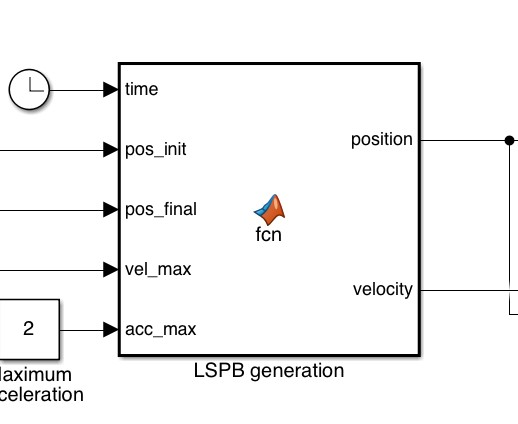

Figure 1: planner using in Simulation

### Control-Loop Frequency

According to the lecture that we had learnt, the control-loop frequency must greater than 10 times of process-time constant or used time to reach 63.2% of final value.

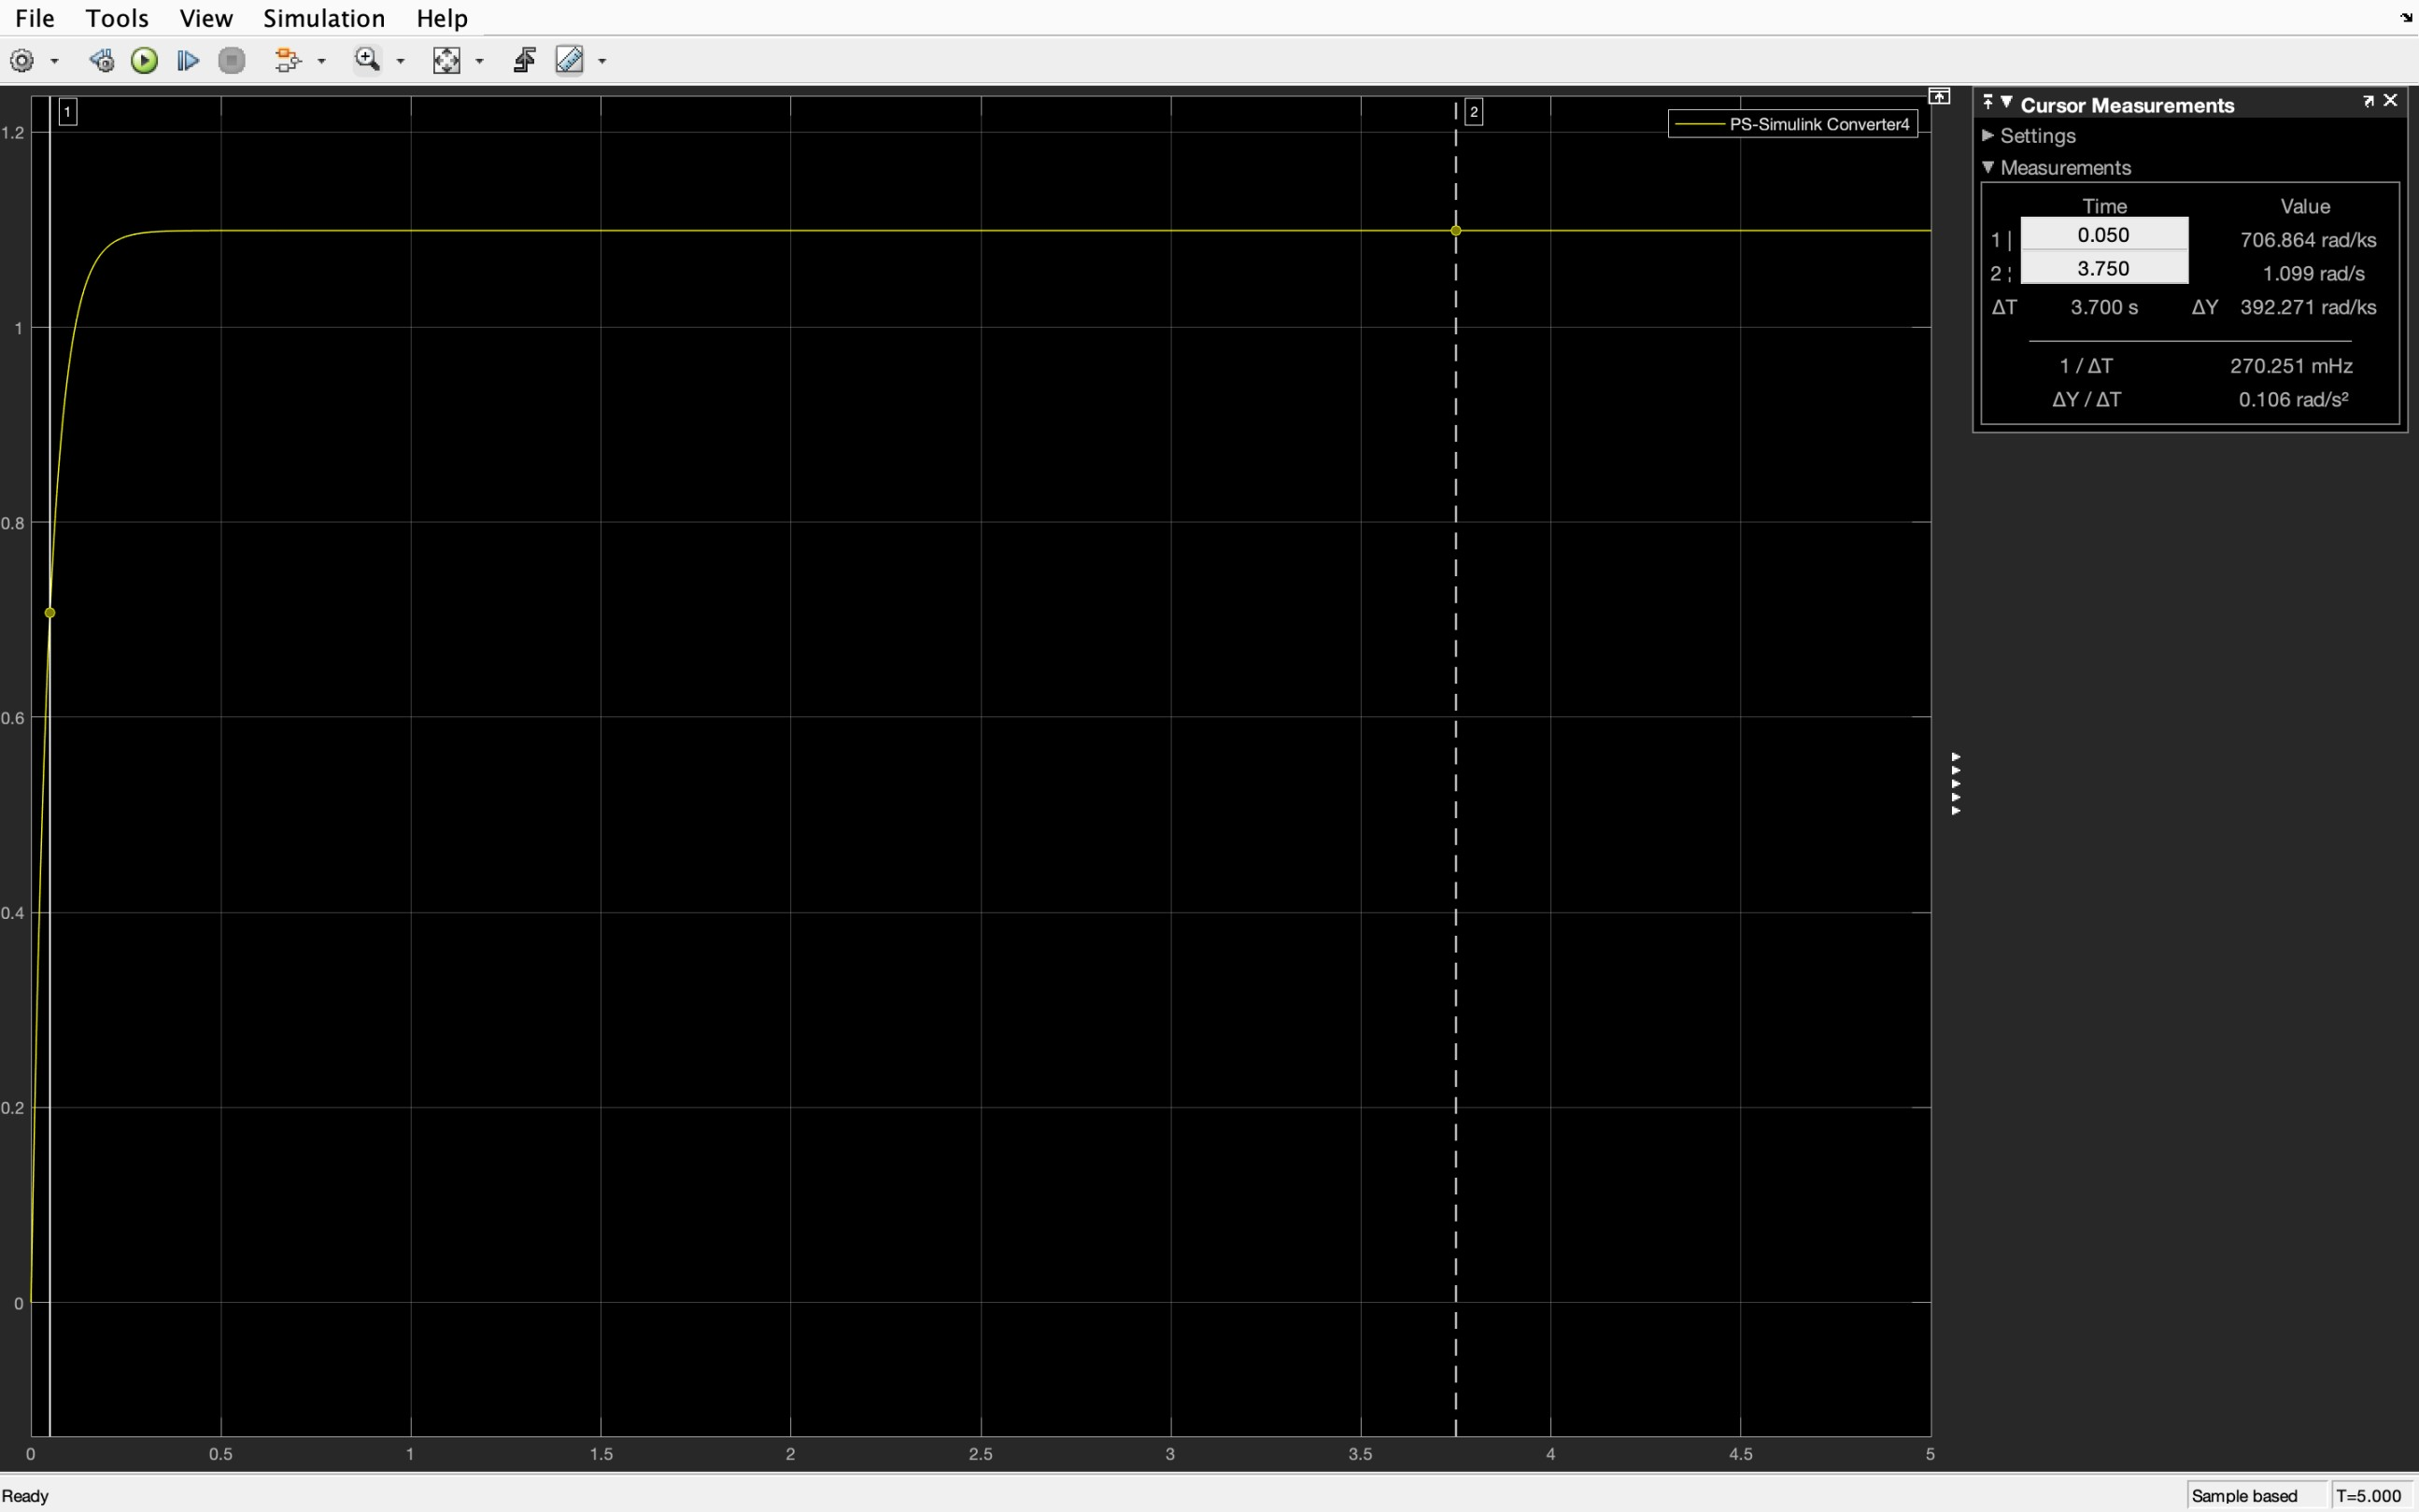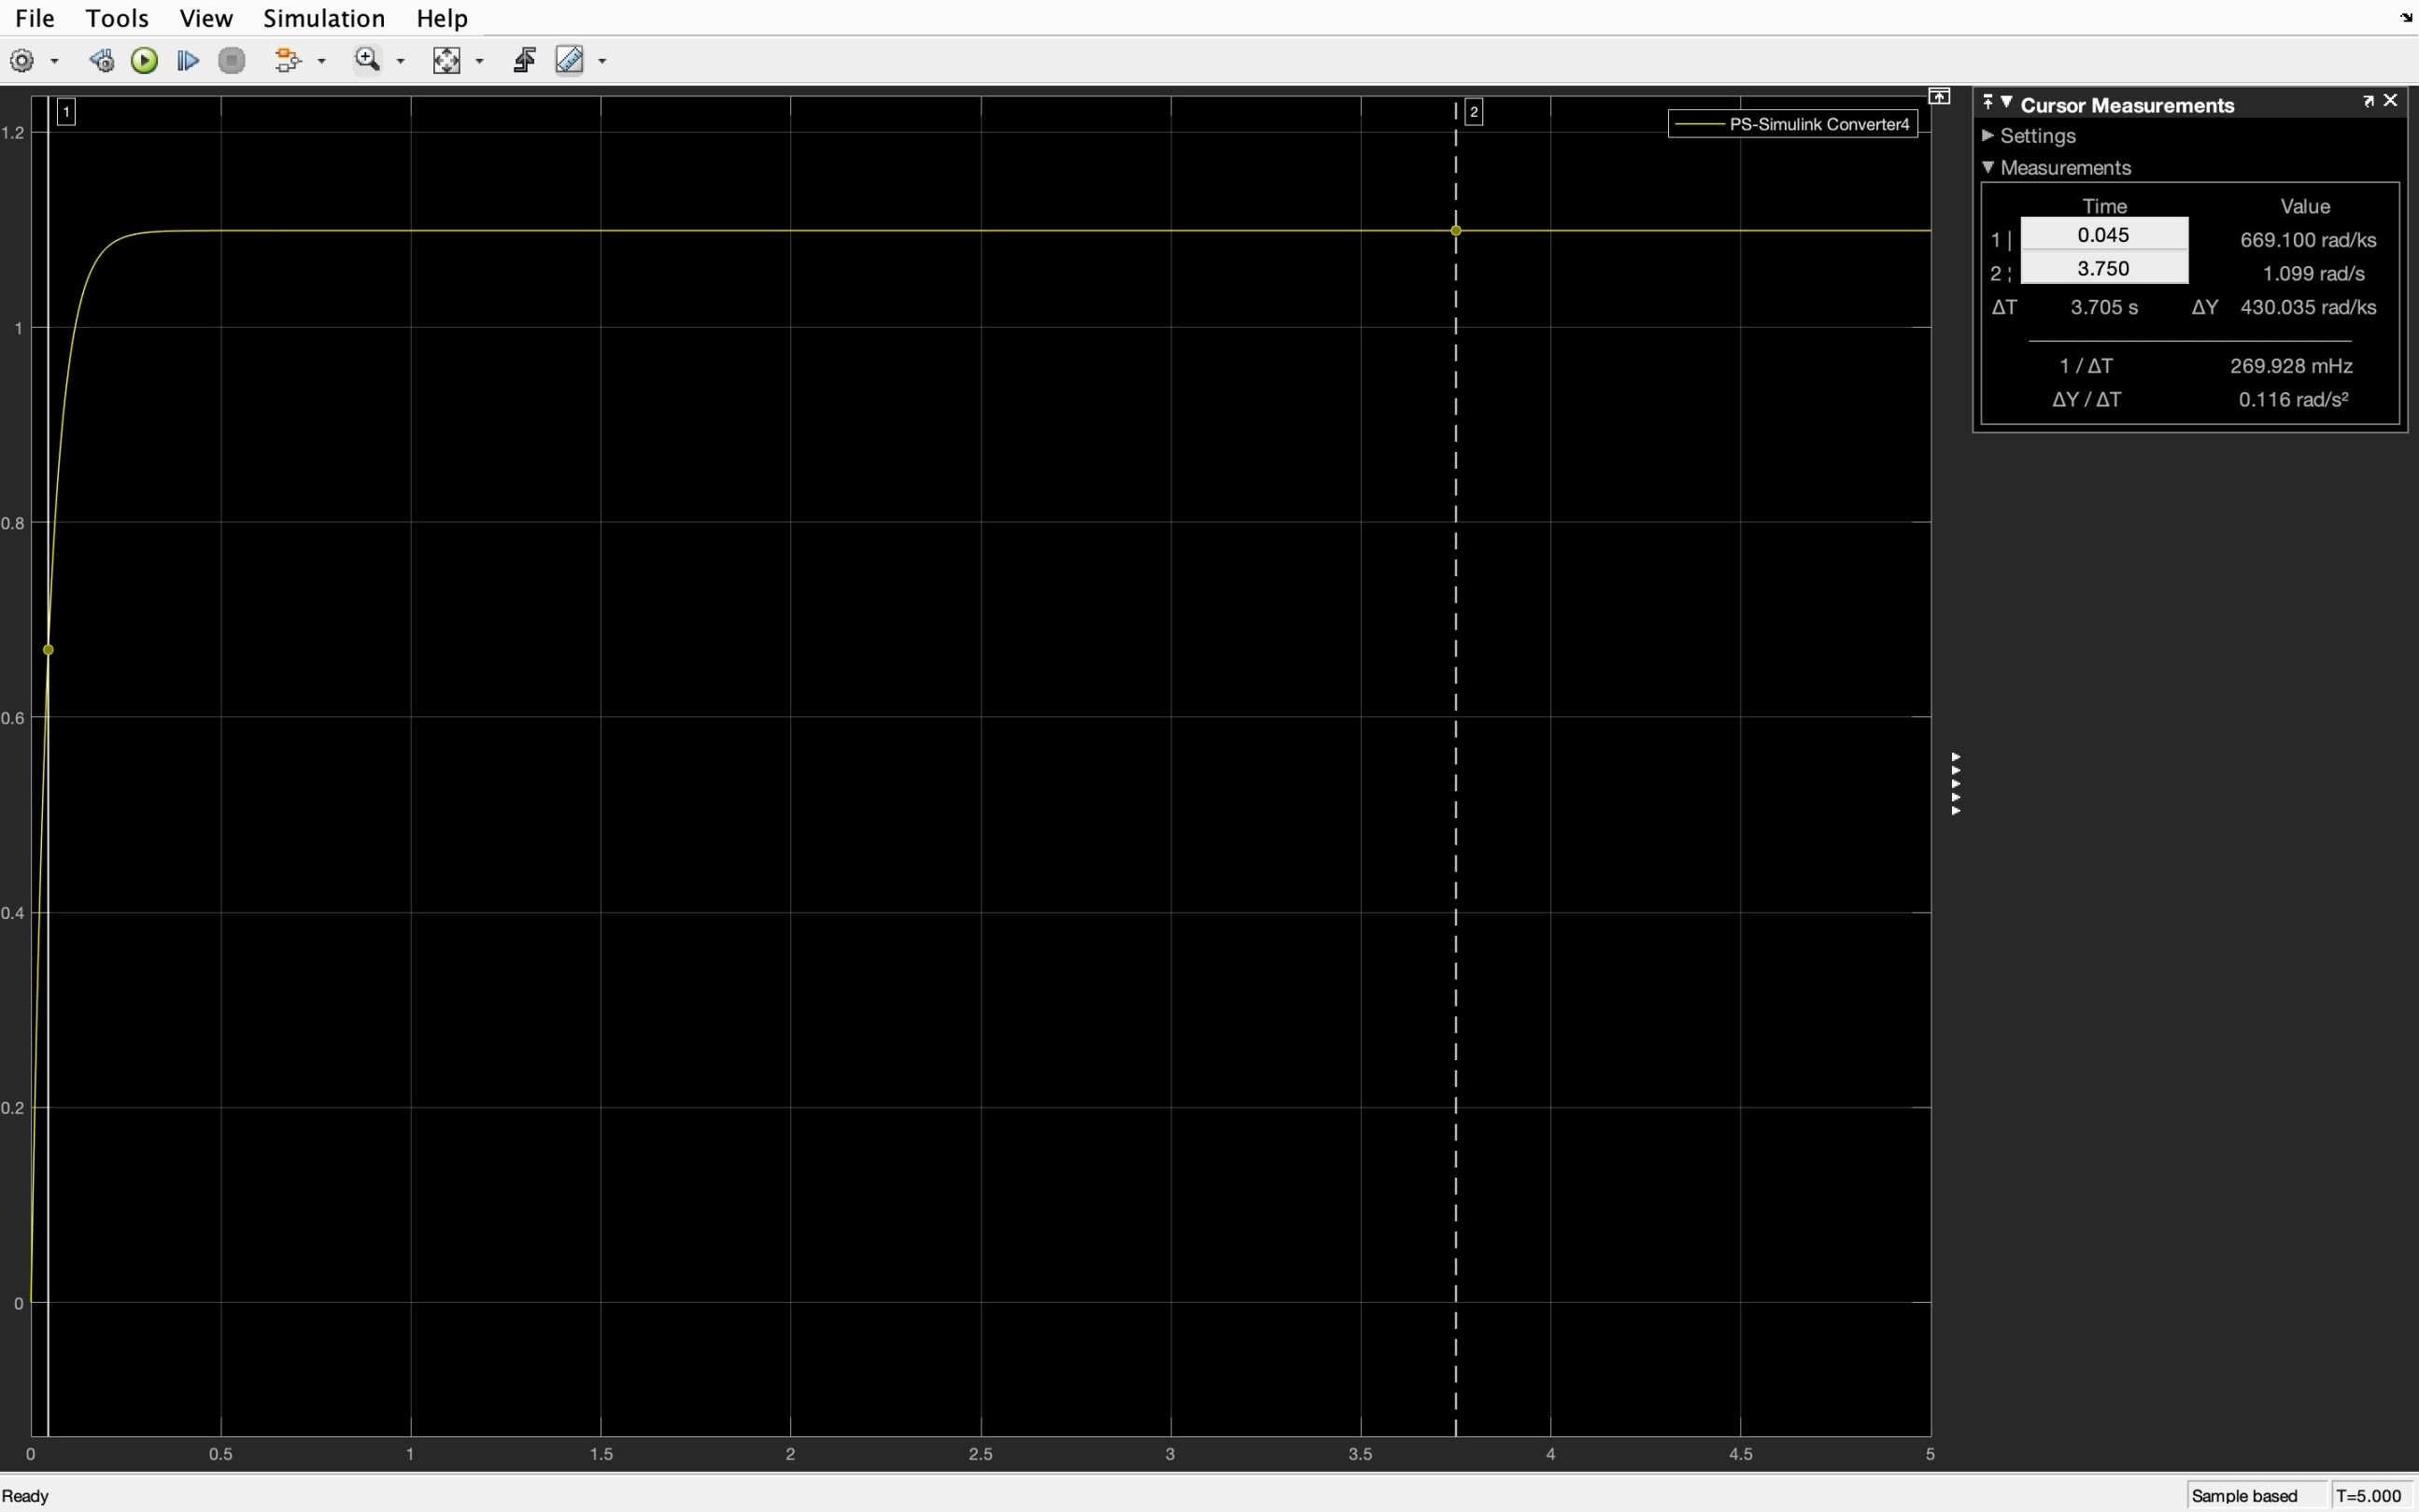

Figure 2: signal of the plant from scope for finding process-time constant

Due to the figure 2, the process-time constant of the system has the value between 0.045 - 0.050 seconds. Therefore the process-time frequency is lower than 23 Hz. Thus, the control-loop frequency must be greater than 230 Hz, and in this experiment we use 1000 Hz.

### Lowpass filter

In order to select the pass band of the lowpass filter, we need to know the bandwidth of the system. Due to the lesson we had learnt, the bandwidth frequency of the system is located at -3dB, such that the bandwith frequency of this plant is 1.6 Hz as in the figure 3.

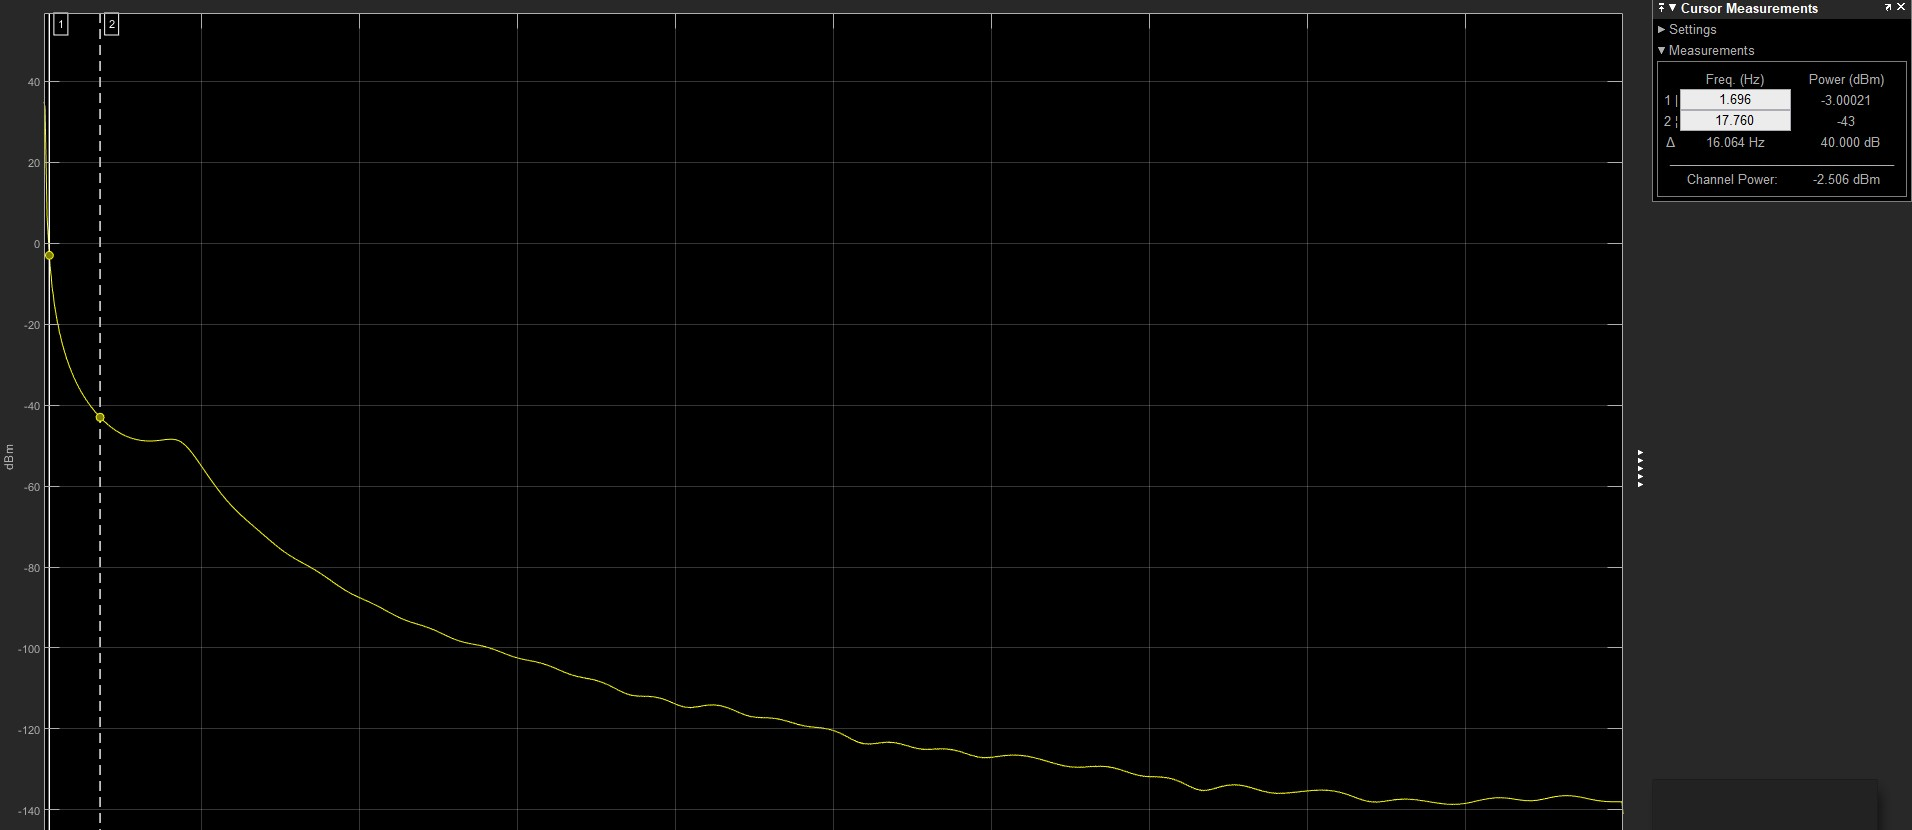

Figure 3: signal of the plant before adding noise from the spectrum analyser

Furthermore, due to the requirement which system must compensate noise consisting 40 dB as the SNR value. Therefore, the Lowpass filter block will be filled as in figure 4.

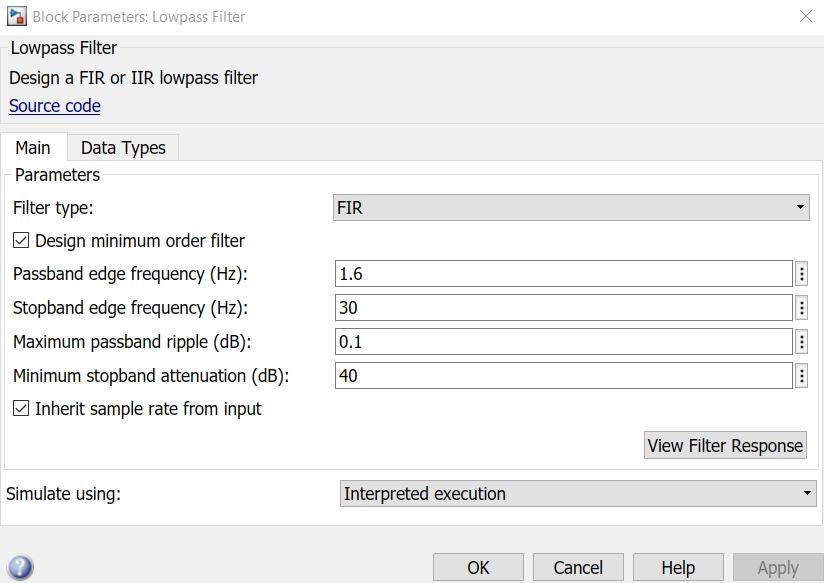

Figure 4: blcok parameter of Lowpass filter

To verify that the selected parameter in the lowpass filter box, the noise must add into the system. In this experiment we used Random Number block is used with thw parameter as following,

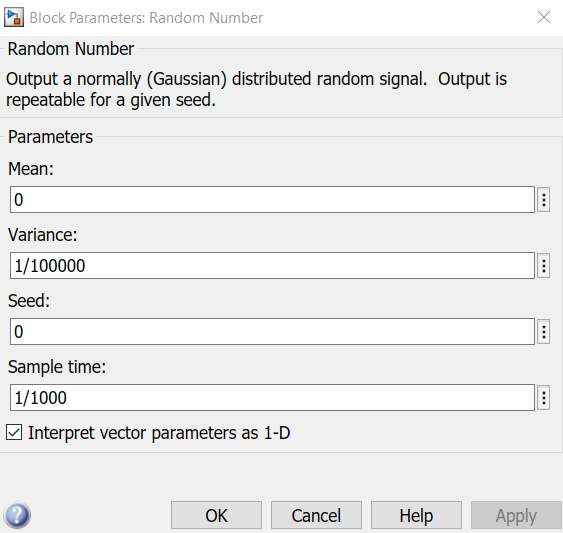

Figure 5: block parameter Random Number

The signal of the plant results as follow,

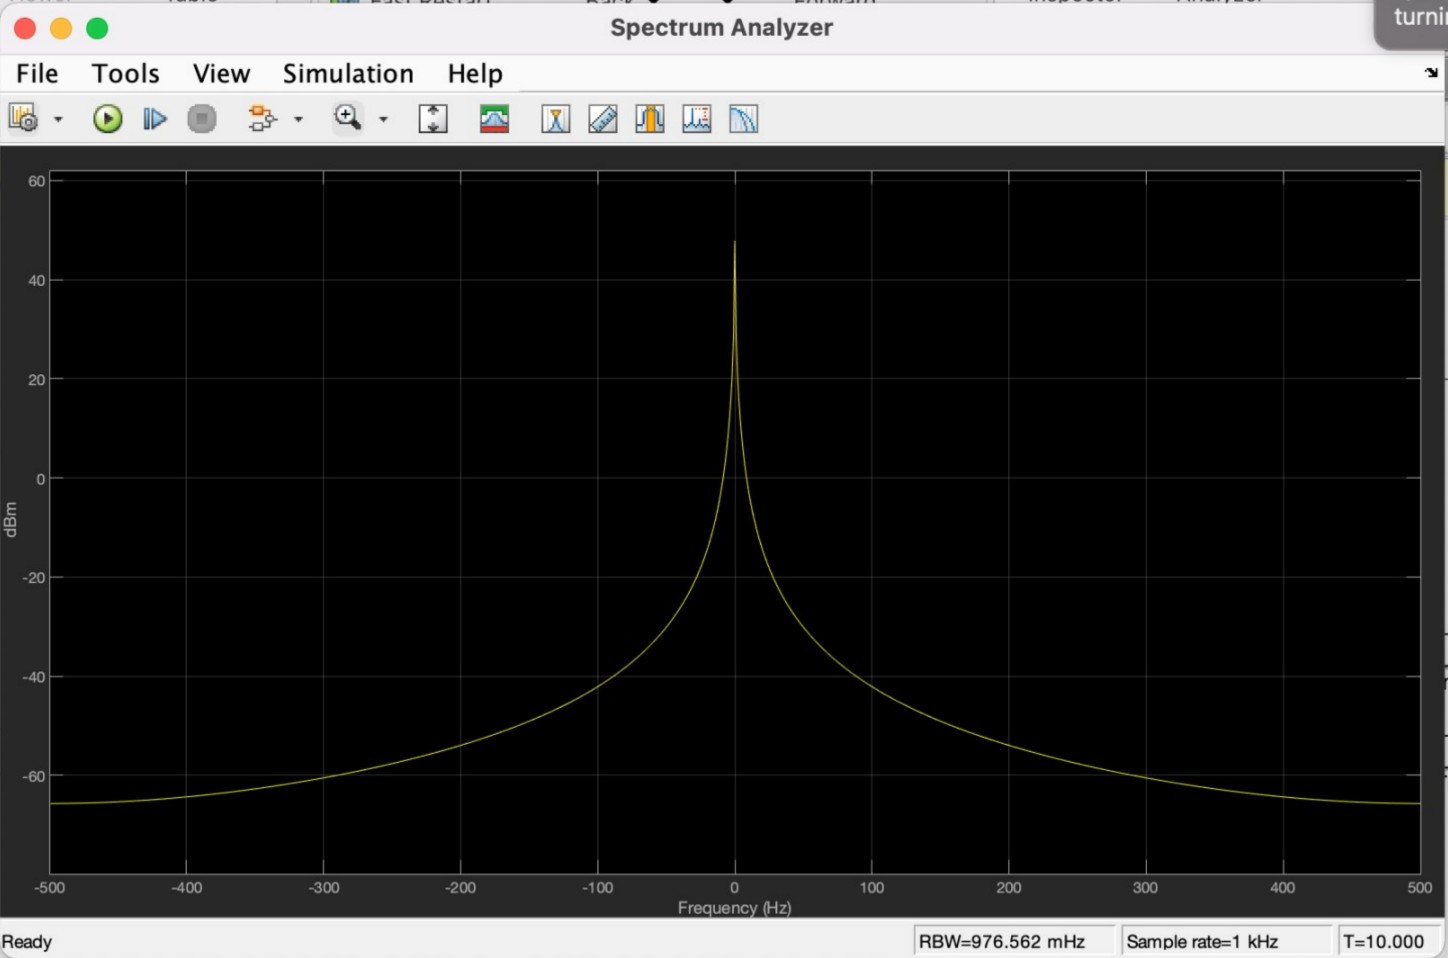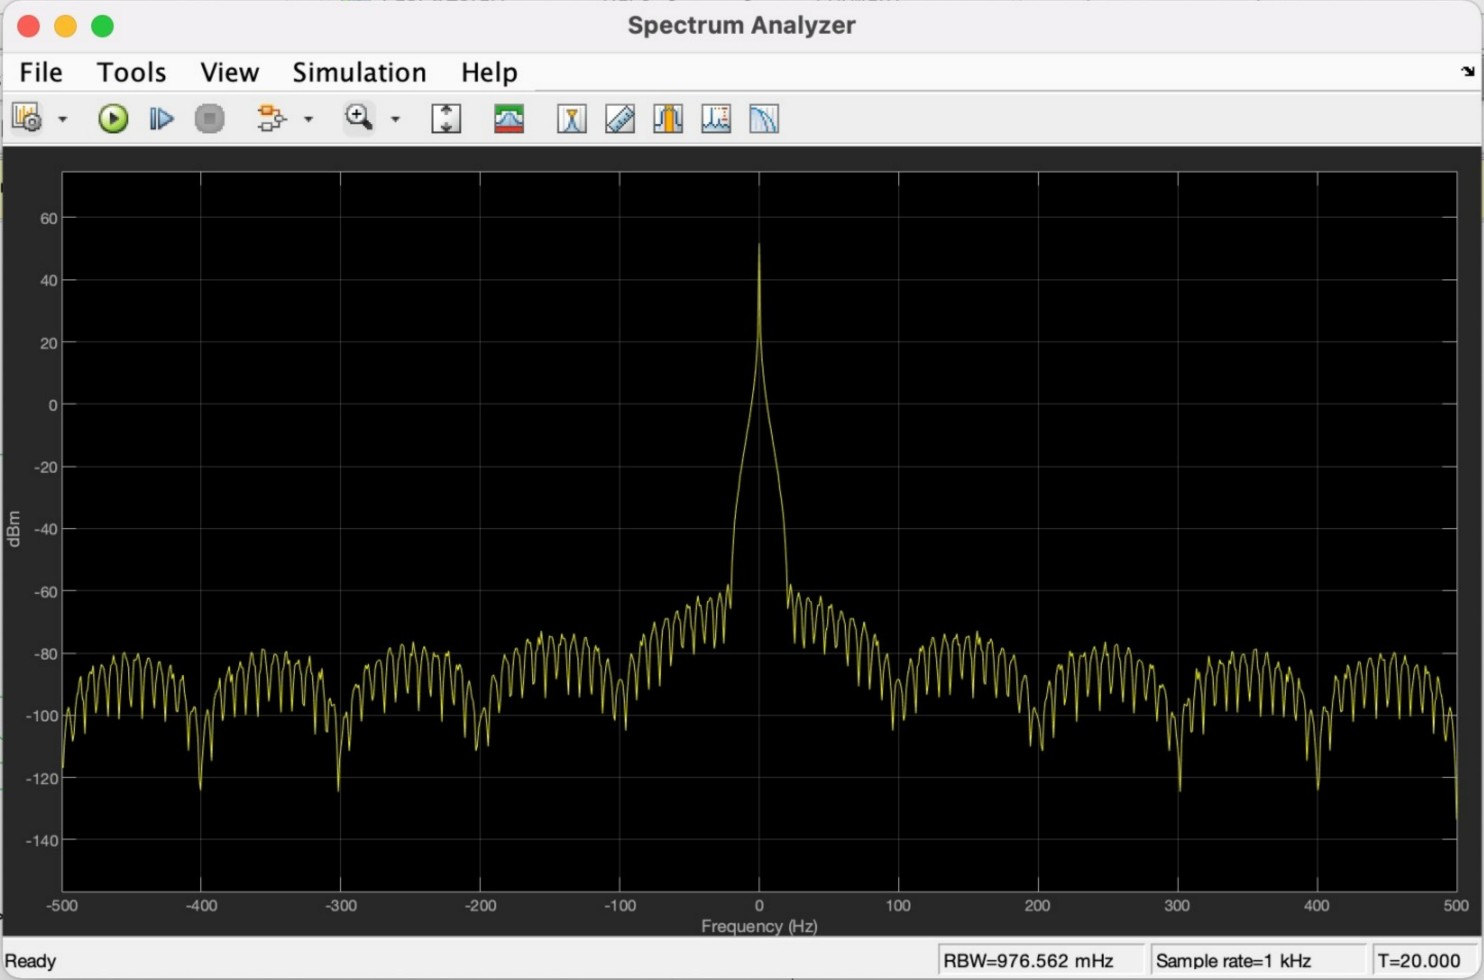

Figure 6: signal of the plant observed from spectrum analyzer before adding nosie and lowpass filter (left), and after nosie and lowpass filter (right)

The used signal of the plant located above 20 dB while the average value of the noise after compensate is located around -90 dB, which will make the SNR value of our system is greater than 40 dB.

### PID Controller

To control the system we place PID as in figure 7 with parameter as in figure 8.

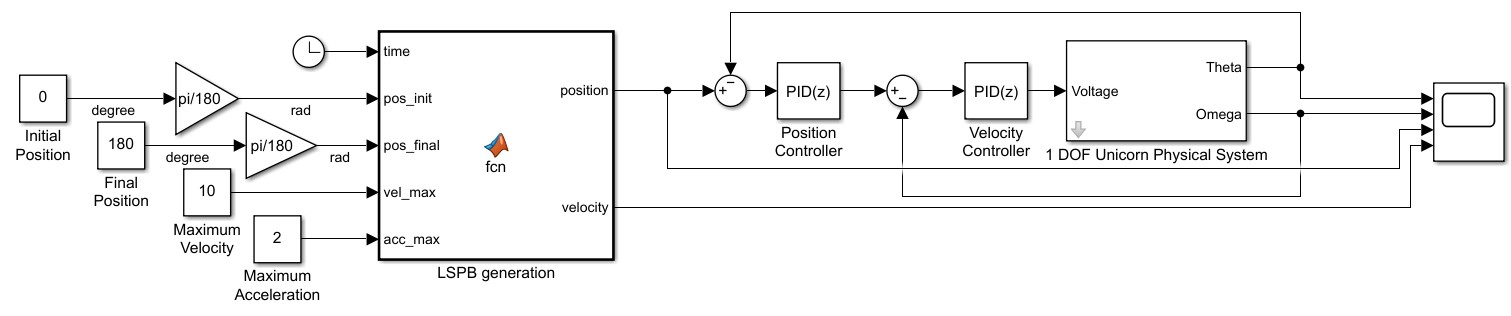

Figure 7: virtual plant after adding planer and controller

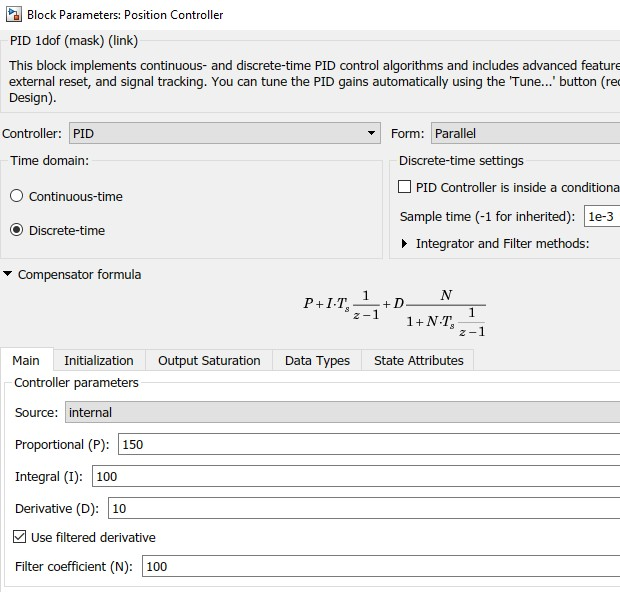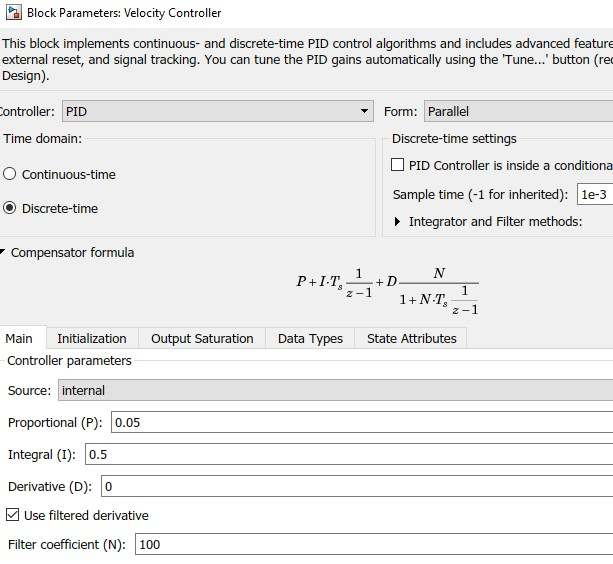

Figure 8: PID parameter of PID position controller (left) and PID velocity controller (right)